## Problem definition

The purpose of this optimiser is to optimise pressure loss across both sides of the heat exchanger and its feeds systsem as well as minimise the Length of the heat exchanger for a set heat transfer Q

Heat load and pressure requirements -> Simscape calculates geometry -> converted into cost function

prob = optimproblem(...
   "Description", "Pipe and HX: system for cost, weight, and length");
mdl = 'pipe_and_hx';

## Variables

designVariableNames = ["dp_pipe";"dp1_HX";"dp2_HX"];
sizingVariables = optimvar("sizingVariables", designVariableNames);
sizingVariables.LowerBound = [ 0.01, 0.1, 2 ];
sizingVariables.UpperBound = [ 10, 10, 30];

Q_Nom = -10000;     % W

## Parameters    

costFunction = fcn2optimexpr( @optimSizingCost, sizingVariables, mdl, Q_Nom, "OutputSize", [1, 3],...
    "Analysis","off",...
    "ReuseEvaluation", true );
prob.Objective = costFunction;

## Define the constraints.

% pressure drop constraint
dp1_constraint = sizingVariables(1) + sizingVariables(2) <= 11;
prob.Constraints.dp1_constraint = dp1_constraint;

% volume constraint
volume_constraint = costFunction(1) <= 0.05;
prob.Constraints.volume_constraint = volume_constraint;

% cost constraint
cost_constraint = costFunction(2) <= 10000;
prob.Constraints.cost_constraint = cost_constraint;

% overall length of the system
length_constraint = costFunction(3) >= 5;
prob.Constraints.length_constraint = length_constraint;

Show the problem.

show(prob)


  OptimizationProblem : Pipe and HX: system for cost, weight, and length

	Solve for:
       sizingVariables

	minimize :
       optimSizingCost(sizingVariables, extraParams{1}, (-10000))

       extraParams


	subject to dp1_constraint:
       sizingVariables('dp_pipe') + sizingVariables('dp1_HX') <= 11

	subject to volume_constraint:
       arg_LHS <= 0.05

       where:

             arg2 = optimSizingCost(sizingVariables, extraParams{1}, (-10000));
             arg_LHS = arg2(1);

       extraParams

	subject to cost_constraint:
       arg_LHS <= 10000

       where:

             arg2 = optimSizingCost(sizingVariables, extraParams{1}, (-10000));
             arg

## Define an initial value for the problem.

x0.sizingVariables = [ 0.01, 0.1, 5 ];

## Solve the problem.

Solve the problem to obtain the optimal set of design variables

Since the model will be simulated repeatedly during the optimization process, enable fast restart mode before calling `solve`.

open_system(mdl);                             % Load the model

paretoOpts = optimoptions( "paretosearch", ...
    'MaxFunctionEvaluations', 300, ...
    'Display','iter',...
    'PlotFcn', { @psplotparetof, @psplotparetox } )

paretoOpts =   paretosearch options:

   Set properties:
                     Display: 'iter'
      MaxFunctionEvaluations: 300
                     PlotFcn: {@psplotparetof  @psplotparetox}

   Default properties:
         ConstraintTolerance: 1.0000e-06
               InitialPoints: []
               MaxIterations: '100*(numberOfVariables+numberOfObjectives)'
                     MaxTime: Inf
               MeshTolerance: 1.0000e-06
             MinPollFraction: 0
                   OutputFcn: []
    ParetoSetChangeTolerance: 1.0000e-04
               ParetoSetSize: 'max(numberOfObjectives, 60)'
                  PollMethod: 'GPSPositiveBasis2Np2'
                 UseParallel: 0
               UseVectorized: 0


Solving problem using paretosearch.

Iter   F-count   NumSolutions  Spread       Volume 
   0        38         9          -         2.4896e+01
   1       232        25       9.9755e-01   2.9428e+01
   2       300        33       3.4718e-01   2.9428e+01

Paretosearch stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.



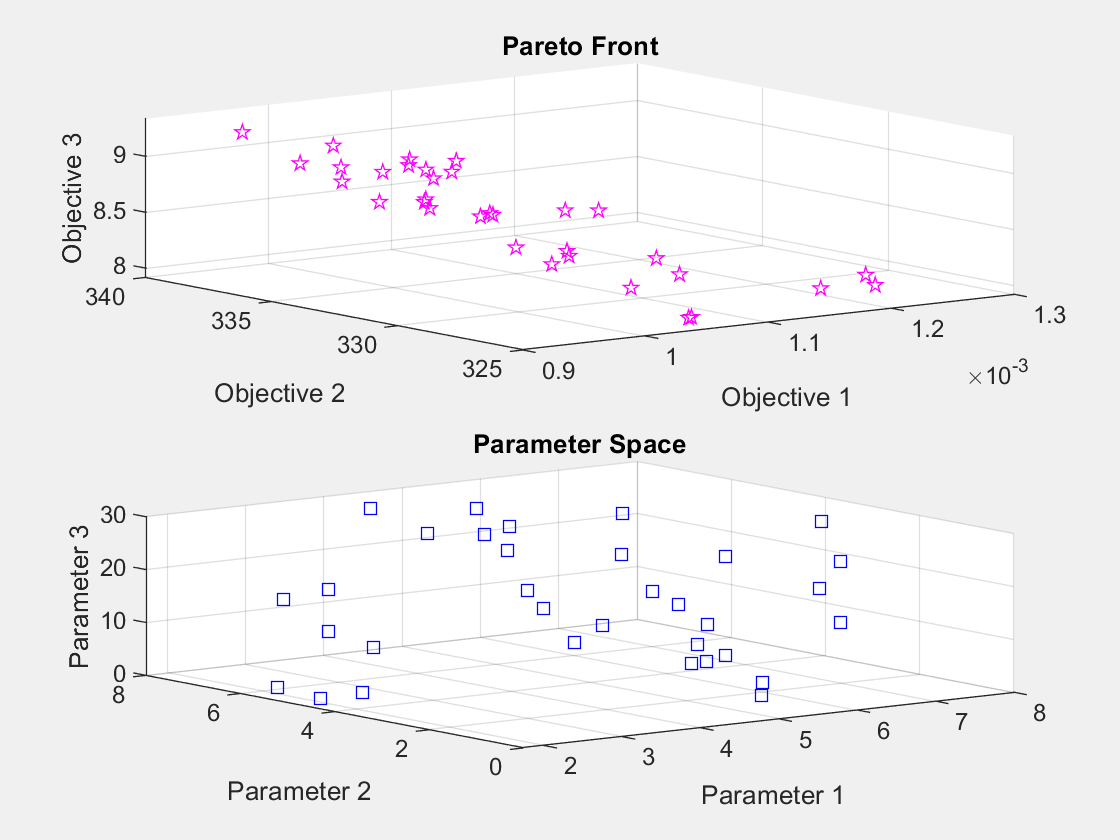

set_param( mdl, "FastRestart", "On" );
tic;
sol = solve(prob,"Solver","paretosearch","Options",paretoOpts);

toc;

Elapsed time is 232.739520 seconds.


set_param( mdl, "FastRestart", "off");      % Fast restart doesn't dirty the model as can't be saved

[fval, g] = sizingCost( sol(4).sizingVariables, mdl, Q_Nom );
disp( g )

    area_pipe: 6.3808e-05
         l_HX: 3.9349
         r_in: 0.0057
        r_out: 0.0071




results = table(designVariableNames, sol.sizingVariables, ...
    'VariableNames', ["Variable", "Optimal Value"])

results = 3×2 table
    Variable     Optimal Value
    _________    _____________

    "dp_pipe"     1×33 double 
    "dp1_HX"      1×33 double 
    "dp2_HX"      1×33 double 


## Objective function:

function FVAL = optimSizingCost( sizingVariables, mdl, Q_Nom )
    [FVAL,~] = sizingCost( sizingVariables, mdl, Q_Nom );
end

function [ FVAL, g ] = sizingCost( sizingVariables, mdl, Q_Nom )

% pass geometry
dp_pipe = sizingVariables(1);
dp1_HX = sizingVariables(2);
dp2_HX = sizingVariables(3);

% Simulation Input object
in = Simulink.SimulationInput(mdl);   % Create simulation input object
    % Configuration
in = in.setModelParameter('SaveTime', 'on', ...
    'SaveOutput', 'on');
in = in.setVariable('Tend',0);
in = in.setVariable('Q',Q_Nom);
    % Design Variables
in = in.setVariable('dp_pipe', dp_pipe);
in = in.setVariable('dp1_HX', dp1_HX);
in = in.setVariable('dp2_HX', dp2_HX);

% simulate
try
    % Simulate a given topology
    simOut = sim( in );

    % optimal geometry
    area_pipe = simOut.logsout.getElement("area_pipe").Values.Data(end);
    l_HX = simOut.logsout.getElement("l_HX").Values.Data(end);
    r_in = simOut.logsout.getElement("r_in").Values.Data(end);
    r_out = simOut.logsout.getElement("r_out").Values.Data(end);

    %cost function
    FVAL(1) = 5 * area_pipe + l_HX * pi * r_out.^2 ; % Volume
    FVAL(2) = 100 * 5 * (2*pi*sqrt(area_pipe / pi)) + 1000 * l_HX * ( 2*pi*r_out + 2*pi*r_in ); % Cost (scales with surface area)
    FVAL(3) = 5 + l_HX; % Length

    g = struct( "area_pipe", area_pipe, "l_HX", l_HX, "r_in", r_in, "r_out", r_out );
catch
    %cost function
    FVAL(1) = inf;
    FVAL(2) = inf;
    FVAL(3) = inf;
    g = struct.empty;
end

end % objective